Turn the synthetic data into fully co-cluster ones

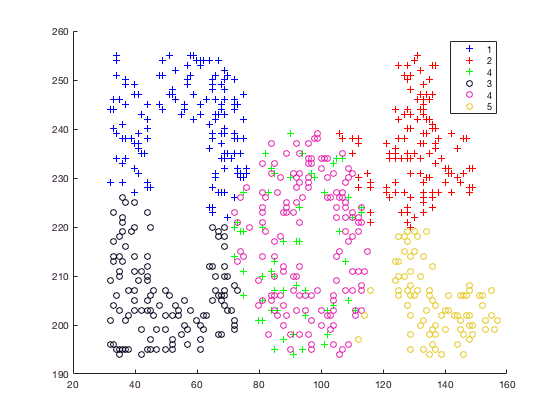

close all
clear all
clc

rng(213);
load('./Data/dot.mat');     % load the associated data file into work space
% Feature Matrix: X -- M x D     Y -- N x D
% Class Name: lx -- M x1     ly -- N x 1

figure
Plotcluster(X', lx, Y', ly);

 Identify the class label with the images

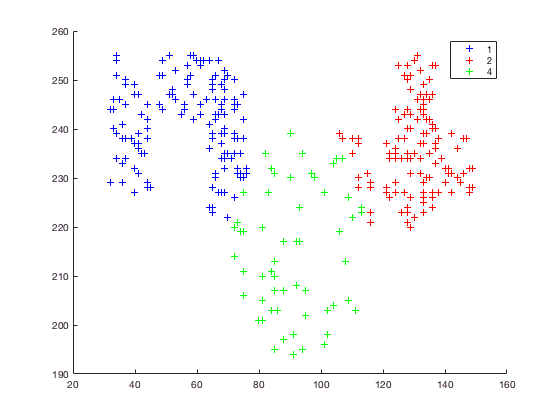

figure 
Plotcluster(X', lx);

% in the dot dataset, (1,3), (2,5) and (4,4) is within the same cluster

Make all data within the same cluster the same

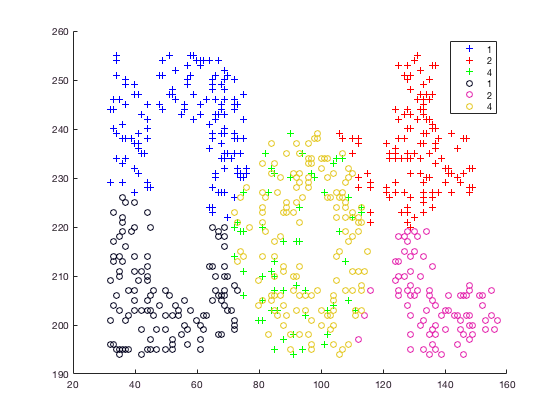

id3 = find(ly == 3);
ly(id3) = 1;

id5 = find(ly == 5);
ly(id5) = 2;

figure 
Plotcluster(X', lx, Y', ly);

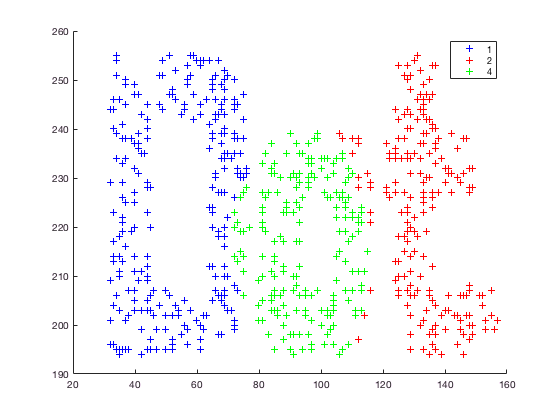


Data = [X; Y];
ldata = [lx; ly];
figure
Plotcluster(Data', ldata);

% Now the only available information is in Data, ldata

Correct the visually bad spots

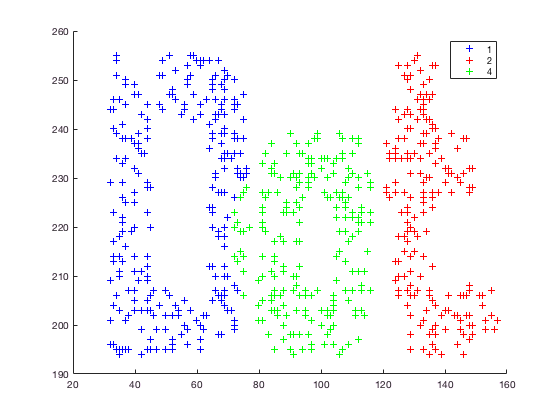

label2 = find(ldata == 2);
set1 = find(Data(:,1) < 120);
badlabel_in2 = intersect(label2, set1);
ldata(badlabel_in2) = 4;
figure
Plotcluster(Data', ldata);

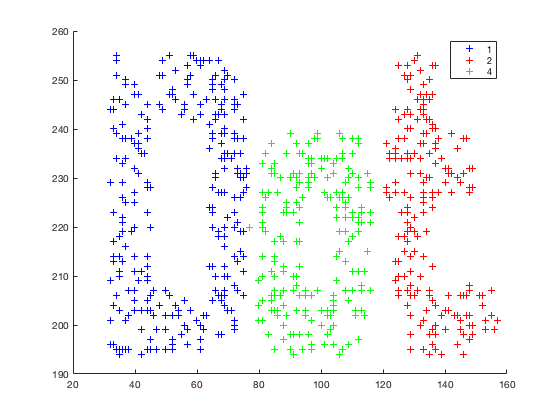


label4 = find(ldata == 4);
set2 = find(Data(:,1) < 77);
badlabel_in4 = intersect(label4, set2);
ldata(badlabel_in4) = 1;
figure
Plotcluster(Data', ldata);

Sampling the coclusters from this data with different sampling rate

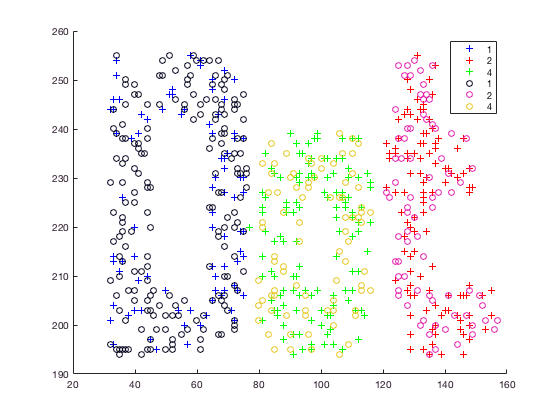

label1 = find(ldata == 1);
num_points = length(label1);
nb_label1_inX = floor(0.3*num_points);
seq = randperm(num_points);
xlabel1 = label1(seq(1:nb_label1_inX));
temp = seq((nb_label1_inX+1) : end);
ylabel1 = label1(temp);

label2 = find(ldata == 2);
num_points = length(label2);
nb_label2_inX = floor(0.6*num_points);
seq = randperm(num_points);
xlabel2 = label2(seq(1:nb_label2_inX));
temp = seq(nb_label2_inX+1 : end);
ylabel2 = label2(temp);

label4 = find(ldata == 4);
num_points = length(label4);
nb_label4_inX = floor(0.6*num_points);
seq = randperm(num_points);
xlabel4 = label4(seq(1:nb_label4_inX));
temp = seq((nb_label4_inX+1) : end);
ylabel4 = label4(temp);

% The new split
lx = ldata([xlabel1; xlabel2; xlabel4]);
ly = ldata([ylabel1; ylabel2; ylabel4]);
X = Data([xlabel1; xlabel2; xlabel4],:);
Y = Data([ylabel1; ylabel2; ylabel4],:);
figure
Plotcluster(X', lx, Y', ly);

Now save the cocluster version of data

save codot.mat X lx Y ly